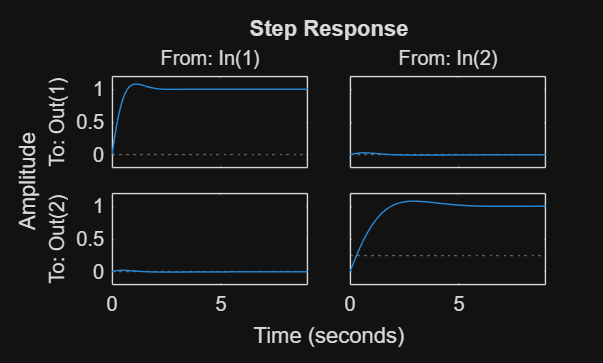

g11=tf(2,[0.6 1]);
g12=tf(0.1,[0.7 1]);
g21=tf(0.4,[0.9 1]);
g22=tf(5,[1.5 1]);
Gp=[g11 g12;g21 g22];

s=tf('s');
Gr1=0.7+2.38/s;
Gr2=0.26+0.35/s;
Gr=[Gr1 0;0 Gr2];
Gs=series(Gp,Gr);
Gf=feedback(Gs,eye(2));

step(Gf)

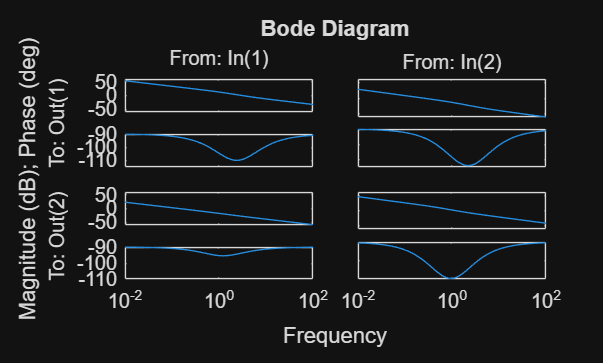


bode(Gs)

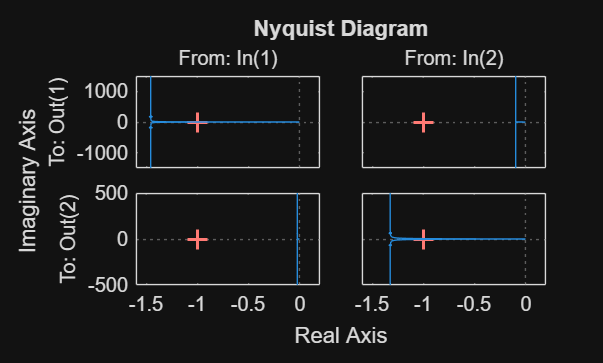

nyquist(Gs)